Psuedocode for Guidance Algorithm:

Outer While Loop (true vehicle state) + (1.0 s)

    Take current state (r,v)

    assume a constant bank angle

    Inner Loop (propogate with bank angle till it hits the ground)

        compute range error

        compute phi_CMD

        progopogate for 1s

        update true vehicle state

Setup for constants and values

Vinf = 5*10^3; % m/s
mu_p = 4.282837*10^13; %m^3/s^2 grav param mars
re = 3389.5*10^3+135*10^3;
Vei = sqrt(Vinf^2+2*mu_p/re);
sigma = 10;
sigma2 = 180;
tspan = [0 1000000];
y01 = [re,0,0,Vei,deg2rad(-25),0,0];
y02 = [re,0,0,Vei,deg2rad(-14),0,0];
y03 = [re,0,0,Vei,deg2rad(-14),0,0];
y04 = [re,0,0,Vei,deg2rad(-30),0,0];
s_goal = 800*10^3;

y0 = [re,0,0,Vei,deg2rad(-14),0,0];
tstep = 1;
y_final = y0;
t_final = [0];
sigma_history = [];

Loop for guidance

%iterates while above fixed height, for this example the ground
%Run for one or two iteration to see how it behaves
%break down some of the code into functions to make more digestible
%If that doesn't work, create dispersions of sigma to argue that function
%can be found but not in current time frame
%while y0(1) > 0
while (y0(1)-3389.5*10^3) > 0
%for index = 0:4
    %calculate current trajectory
    [t,y] = ode45(@(t,y)entrydynamics(t,y,sigma),tspan,y0);
%     plot(y(:,7),(y(:,1)- 3389.5*10^3)/1000)
%     yline(0);
%     % find time of impact
%     t_impact = find(y(:,1) > 0, 1, 'last'); 
%     %Finds the predicted downrange at that time
%     s_predicted = y(t_impact,7);
%     %calculates error
%     s_error = s_goal - s_predicted;
%     %if greater than 0 then add to bank angle
    s_error = downrangeError(t,y,s_goal);
    s_error/1000;
    sigma = bankAngleUpdate(s_error,sigma);
    t_step_index = find(t > tstep,1,'first');
    t_final = [t_final; t(t_step_index)];
    y0 = y(t_step_index,:);
    %y0(1) - 3389.5*10^3;
    y_final = [y_final; y0];
    sigma_history = [sigma_history; sigma];
    tstep = tstep + 0.5;
end

Plotting Section to Visualize Results

t_final

t_final =          0
    1.0801
    1.9740
    2.1447
    2.8283
    3.0499
    4.0079
    4.2684
    4.5629
    5.3526


y_final(24,7)

ans = 8.1667e+05

y_final(:,1) - 3389.5*10^3

ans = 	1.0e+05 *

    1.3500
    1.3317
    1.2987
    1.2633
    1.2175
    1.1693
    1.1076
    1.0440
    0.9786
    0.9053


sigma_history

sigma_history =     25
    10
    25
    10
    25
    10
    25
    10
    25
    10


maxV = max(y_final(:,4))

maxV = 7.0406e+03


[t1,y1] = ode45(@(t,y)entrydynamics(t,y,sigma),tspan,y02);

[t2,y2] = ode45(@(t,y)entrydynamics(t,y,sigma2),tspan,y02);


figure()

plot(y_final(:,7)/1000,(y_final(:,1)- 3389.5*10^3)/1000,'Marker','+')
hold on
plot(y1(:,7)/1000,(y1(:,1)- 3389.5*10^3)/1000)
plot(y2(:,7)/1000,(y2(:,1)- 3389.5*10^3)/1000)
yline(0)

ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 0
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


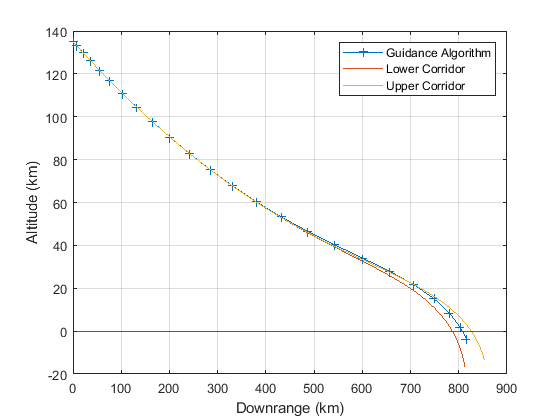

xlabel('Downrange (km)');
ylabel('Altitude (km)');
legend('Guidance Algorithm','Lower Corridor','Upper Corridor');
grid on;


% %Code for analyzing best bank angles
% [t1,y1] = ode45(@(t,y)entrydynamics(t,y,sigma),tspan,y02);
% [t2,y2] = ode45(@(t,y)entrydynamics(t,y,sigma2),tspan,y02);
% 
% s_error = downrangeError(t1,y1,s_goal)
% 
% %plotting various bank angles
% figure()
% plot(y1(:,7)/1000,(y1(:,1)- 3389.5*10^3)/1000)
% hold on;
% %plot(y2(:,7)/1000,(y2(:,1)- 3389.5*10^3)/1000)
% xlabel('Velocity (km/s)');
% ylabel('Altitude (km)');
% %legend('sigma0','sigma180')
% grid on;

Density Function

function rho = density(r)
r_mars =  3389.5*10^3; % in m
alt = r-r_mars; %altitude
rho = 0.013*exp(-alt/11000);  %(1/0.013)*e^alt; % density in kg/m^3
end

Dynamics function

function dydt=entrydynamics(t,y,sigma)
%y(r,theta,phi,V,gamma,psi,s)
%dydt (rdot,thetadot,psidot,Vdot,gammadot,psidotsd0t)
 
%sigma = 0;% bank angle
q = 1/2*density(y(1))*y(4)^2;%dynamic pressure
m = 188335.47; % vehicle mass
CD = 1.7;%coeff drag based off aeroshell
A = 50;%Ref Area approx of space shuttle lander
LD = 0.24;%.24 is the MSL; % 0.8 % Lift/Drag approximated from space shuttle, now using from esa's ixv
Beta = 200; %m / (CD*A)%Ballistic Coefficient
mu_p = 4.282837*10^13; %m^3/s^2 grav param mars
gr = -mu_p/y(1)^2;%radial grav component
 
dydt(1)= y(4)*sin(y(5));
dydt(2)= y(4)*cos(y(5))*cos(y(6))/(y(1)*cos(y(3)));
dydt(3)= y(4)*cos(y(5))*cos(y(6))/(y(1));
dydt(4)= -q/Beta + gr*sin(y(5));
dydt(5)= (q*LD)/(y(4)*Beta)*cos(sigma) + 1/y(4)*(gr*cos(5)) + (y(4)*cos(y(5))/y(1));
dydt(6)= (q*LD)/(y(4)*Beta)*sin(sigma)/cos(y(4)) - y(4)/y(1)*cos(y(5))*cos(y(6))*tan(y(3));
dydt(7)= y(4)*cos(y(5));
dydt = dydt';
end

Downrange Error calculator

function [s_error, t_impact] = downrangeError(t,y,s_goal)
    step_impact = find(y(:,1) - 3389.5*10^3 > 0, 1, 'last');
    height_check = y(step_impact,1) - 3389.5*10^3;
    step_check = y(step_impact,7);
    s_predicted = y(step_impact,7);
    s_error = s_goal - s_predicted;
end

Bank Angle Updater

function sigma_new = bankAngleUpdate(s_error,sigma)
    if s_error > 0
            sigma_new = sigma + 15;
            %check to prevent exceeding 180
            if sigma_new > 180
                sigma_new = 180;
            end
    else
        %if lesser than zero subtract from bank angle
        sigma_new = sigma - 15;
        %check for min bank angle
        if sigma_new < 10
            sigma_new = 10;
        end
    end
end 